# Support Vector Machine (SVM)

DOC: [https://es.mathworks.com/discovery/support-vector-machine.html](https://es.mathworks.com/discovery/support-vector-machine.html)

## Cargamos la factorización y entrenamos SVM 

clc, clear, close all

% Cargamos los datos
U = readmatrix('fact_output/U.csv');
V = readmatrix('fact_output/V.csv');
X = readmatrix('fact_output/X.csv');

% Caracterizamos las clases de forma manual para la visualización
Y = U(:,1) > 0;

% Ajustamos el modelo SVM (pesado de compilar)
k = 2;
[idx,C] = kmeans(U,k);

## Visualización de los datos y predicción del modelo SVM

% Generamos un grid para visualizar la predicción
N = 1000;
x_ = linspace(-1.1,1.1,N);
y_ = linspace(-1.1,1.1,N);
[xx,yy] = meshgrid(x_, y_);

% Vectorizamos dichos grids -> serie de puntos
grid_vec = [xx(:),yy(:)];

% Clasificamos todos los puntos del grid
Yp = kmeans(grid_vec,k,'MaxIter',1,'Start',C);

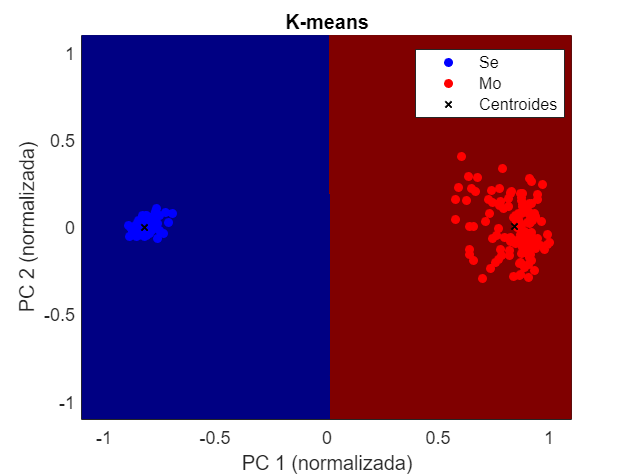


% Dibujamos la figura
Yp_draw    = reshape(Yp         ,size(xx));

figure(1), clf
gscatter(U(:,1), U(:,2), idx, 'br', '.'), hold on
plot(C(:,1),C(:,2),'kx','MarkerSize',5,'LineWidth',1) 
surf(xx,yy,Yp_draw-2), shading interp, colormap jet
view(2)

xlim([-1.1,1.1]), ylim([-1.1,1.1])
legend('Se','Mo','Centroides')
title("K-means")
xlabel("PC 1 (normalizada)")
ylabel("PC 2 (normalizada)")